Question 3)

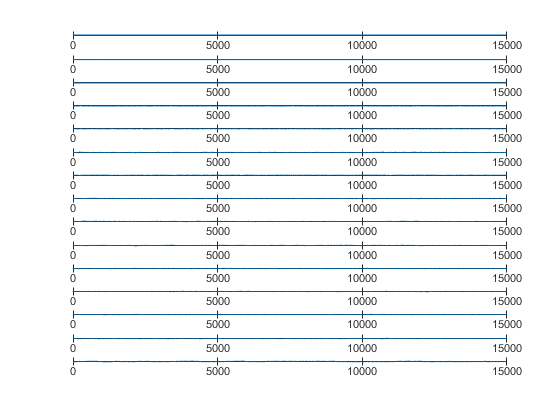

load("Exam\dataexam2020Question3.mat")

mdata = mean(data,2);

data0 = data - mdata;

[U,S,V] = svd(data0,'econ');

A = sqrt(length(data)-1)^(-1)*(U*S);
Z = sqrt(length(data)-1)*V';

figure()
for i = 1:15
    subplot(15,1,i)
    plot((1:length(Z)),Z(i,:))
end

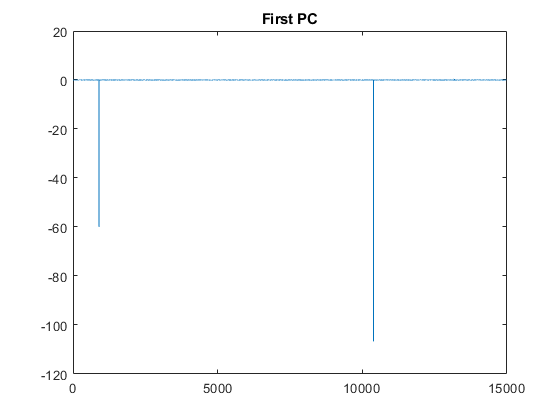

figure()
plot((1:length(Z)),Z(1,:))
title("First PC")

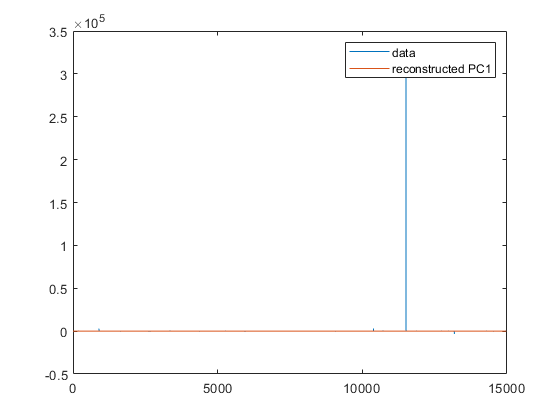

eeg_rec = A(:,2)*pinv(A(:,2))*data0;

figure()
plot((1:length(data0)),data0(1,:))
hold on
plot((1:length(eeg_rec)),eeg_rec(1,:))
hold off
legend('data','reconstructed PC1')

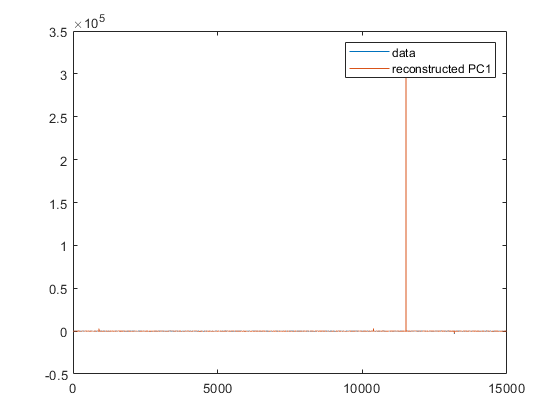

eeg_rec1 = A(:,1:3)*pinv(A(:,1:3))*data0;

figure()
plot((1:length(data0)),data0(1,:))
hold on
plot((1:length(eeg_rec)),eeg_rec1(1,:))
hold off
legend('data','reconstructed PC1')